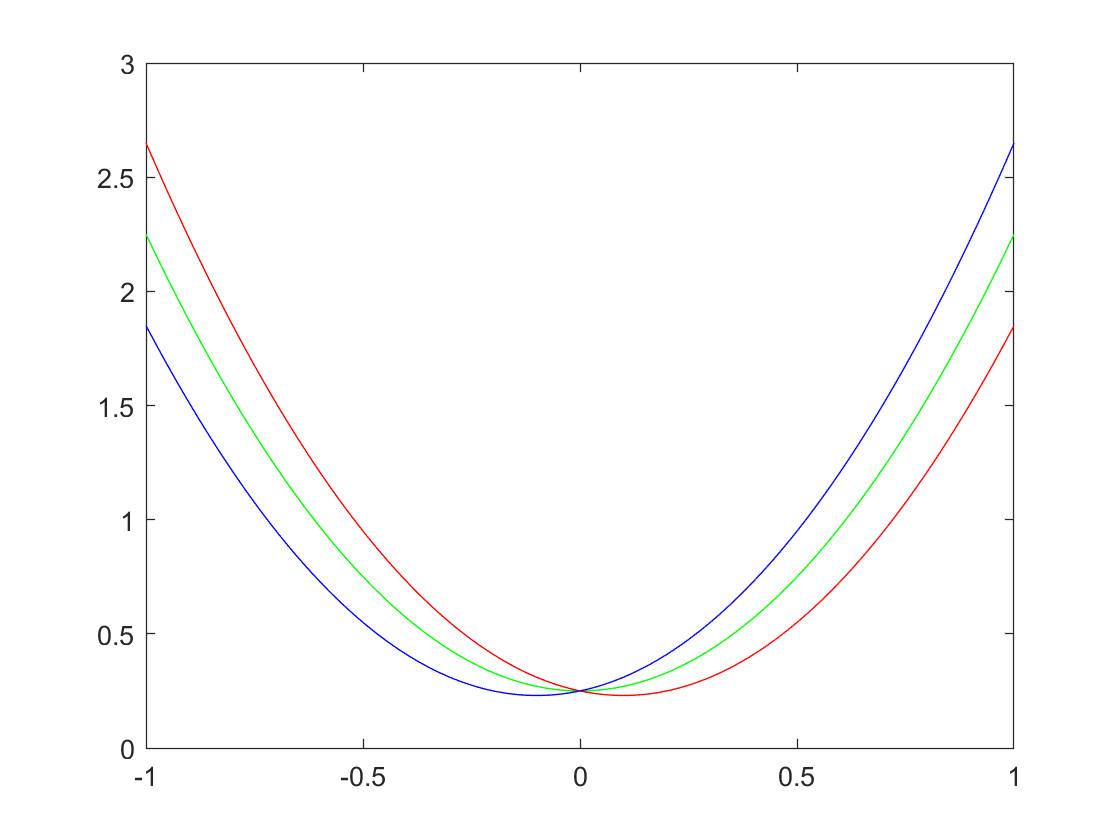

parabola_func = @(x,x0,k) k*(x-x0).^2;
protein_aggre = @(phi,k) k*phi*(1-phi);

x = -1:0.01:1;
hamiltonian_50 = parabola_func(x,0,1) + 0.5*parabola_func(x,-0.5,1) + 0.5*parabola_func(x,0.5,1) + protein_aggre(0.5,0);
hamiltonian_30 = parabola_func(x,0,1) + 0.3*parabola_func(x,-0.5,1) + 0.7*parabola_func(x,0.5,1) + protein_aggre(0.3,0);
hamiltonian_70 = parabola_func(x,0,1) + 0.7*parabola_func(x,-0.5,1) + 0.3*parabola_func(x,0.5,1) + protein_aggre(0.7,0);

plot(x,hamiltonian_50,'g',x,hamiltonian_30,'r',x,hamiltonian_70,'b');

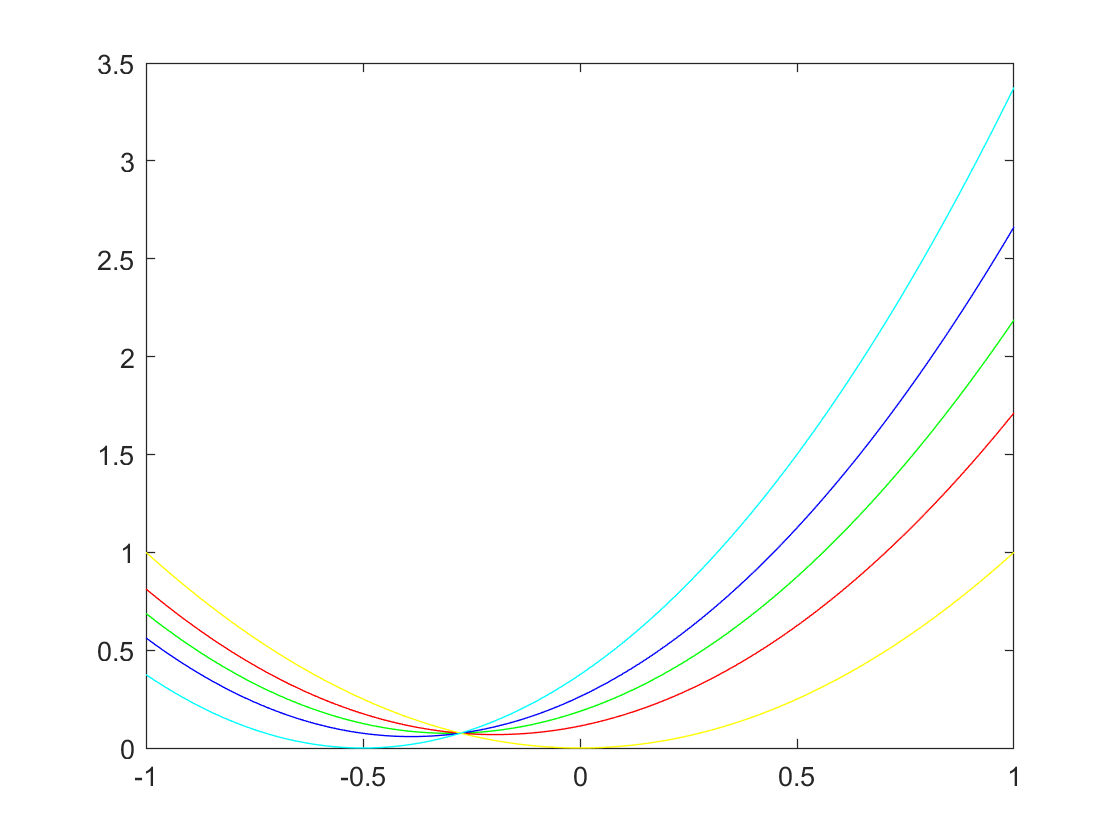


hamiltonian_00 = 1*parabola_func(x,0,1) + 0*parabola_func(x,-0.5,1.5) + 0*0.5*parabola_func(x,0.5,1) + protein_aggre(0.5,0);
hamiltonian_50 = 0.5*parabola_func(x,0,1) + 0.5*parabola_func(x,-0.5,1.5) + 0*0.5*parabola_func(x,0.5,1) + protein_aggre(0.5,0);
hamiltonian_30 = 0.7*parabola_func(x,0,1) + 0.3*parabola_func(x,-0.5,1.5) + 0*0.7*parabola_func(x,0.5,1) + protein_aggre(0.3,000);
hamiltonian_70 = 0.3*parabola_func(x,0,1) + 0.7*parabola_func(x,-0.5,1.5) + 0*0.3*parabola_func(x,0.5,1) + protein_aggre(0.7,000);
hamiltonian_100 = 0*parabola_func(x,0,1) + 1*parabola_func(x,-0.5,1.5) + 0*0.3*parabola_func(x,0.5,1) + protein_aggre(0.7,000);

plot(x,hamiltonian_50,'g',x,hamiltonian_30,'r',x,hamiltonian_70,'b',x,hamiltonian_00,'y',x,hamiltonian_100,'c');